# SMIB Model - Power Step

Single Machine to Infinite Bus Model, using Gomez's eqs 10.3-10.7, with a mechanical-power step from 1.0 to 1.2 pu after 5 s. The AVR voltage reference remains at 1.0 pu.

### Constants

D  = 0.1;
f  = 50;
w0 = 2*pi*f;
H  = 3;
Vinf = 1;
Xd1 = 0.1;
XT  = 0.05;
XL  = 0.5;
Xe = Xd1 + XT + XL;

### Design Parameter

Kv = 1.2;

### Specified Inputs

Pm_init  = 0.9;
Pm_after = 1.1;
tstep = 5;
tend  = 30;
dt = 0.01;                    % Requested output interval, not solver step size
Pm_step = @(t) Pm_init + (Pm_after-Pm_init).*(t >= tstep);
V1o_init = 1.0;                % Fixed AVR voltage reference throughout

% Check BOTH requested steady-state operating points (low-angle branch).
s1 = Pm_init*XL/(Vinf*V1o_init);
s2 = Pm_after*XL/(Vinf*V1o_init);
if abs(s1) >= 1 || abs(s2) >= 1
    error('A requested operating point is at or beyond the PCC transfer limit.');
end

### Initial Conditions

domega0 = 0;
V1mag0 = V1o_init;
delta10 = asin(Pm_init*XL/(Vinf*V1mag0));
delta0 = atan2(Pm_init*Xe/Vinf, ...
    Xe*((V1mag0/XL)*cos(delta10)-Vinf*(1/XL-1/Xe)));
E0 = hypot(Pm_init*Xe/Vinf, ...
    Xe*((V1mag0/XL)*cos(delta10)-Vinf*(1/XL-1/Xe)));
x0 = [delta0; domega0; E0; V1mag0; delta10];

### State Space Equations and Solve

% x = [delta; domega; E; V1mag; delta1]
% delta: internal generator angle; delta1: PCC angle, both relative to Vinf.
% Pm_value is constant within each integration segment.
DynamicsEqs = @(t,x,Pm_value) [ ...
    x(2); ...
    (w0/(2*H))*(Pm_value-(x(3)*Vinf*sin(x(1)))/Xe-D*x(2)); ...
    Kv*(V1o_init-x(4)); ...
    (Vinf*x(4)*sin(x(5))/XL)-(x(3)*Vinf*sin(x(1))/Xe); ...
    (Vinf^2*(1/XL-1/Xe)+(x(3)*Vinf*cos(x(1))/Xe) ...
        -(Vinf*x(4)*cos(x(5))/XL))];

r0 = DynamicsEqs(0,x0,Pm_init);
assert(norm(r0,inf) < 1e-9, 'Initial point is not a consistent equilibrium.');
M = diag([1 1 1 0 0]);
options = odeset('Mass',M,'MassSingular','yes', ...
    'MStateDependence','none','RelTol',1e-8,'AbsTol',1e-10,'MaxStep',0.02);

% Restart exactly at the step so ode15s never steps across a discontinuity.
[tpre,xpre] = ode15s(@(t,x) DynamicsEqs(t,x,Pm_init), ...
    linspace(0,tstep,round(tstep/dt)+1),x0,options);
[tpost,xpost] = ode15s(@(t,x) DynamicsEqs(t,x,Pm_after), ...
    linspace(tstep,tend,round((tend-tstep)/dt)+1),xpre(end,:).',options);
t = [tpre; tpost(2:end)];
x = [xpre; xpost(2:end,:)];

### Calculating PG and QG at each point in time

delta  = x(:,1);
domega = x(:,2);
E      = x(:,3);
V1mag  = x(:,4);
delta1 = x(:,5);
PG = zeros(length(t),1);
QG = zeros(length(t),1);
for n = 1:length(t)
    PG(n) = (V1mag(n)*Vinf/XL)*sin(delta1(n));
    % Reactive power leaving PCC1 into XL, not internal-source reactive power.
    QG(n) = V1mag(n)^2/XL-(V1mag(n)*Vinf/XL)*cos(delta1(n));
end
Pm_trace = Pm_step(t);
df1 = domega/(2*pi);
df_grid = zeros(size(t));
Pe_internal = E*Vinf/Xe.*sin(delta);
Paccelerating = Pm_trace-Pe_internal-D*domega;
RoCoF1 = (w0/(2*H))*Paccelerating/(2*pi);

### Plot

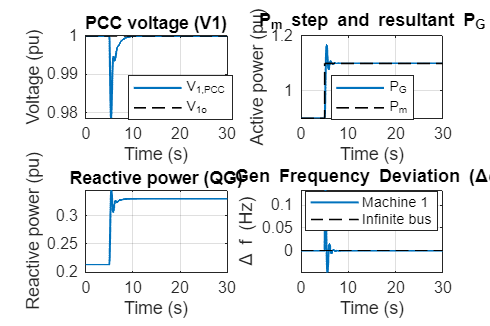

fig = figure('Color','w','Units','inches','Position',[1 1 7.2 4.8]);
subplot(2,2,1);
plot(t,V1mag,'LineWidth',1.3); hold on;
plot(t,V1o_init*ones(size(t)),'k--','LineWidth',1);
xlabel('Time (s)'); ylabel('Voltage (pu)');
legend('V_{1,PCC}','V_{1o}','Location','best');
title('PCC voltage (V1)'); grid on; xlim([0 tend]);

subplot(2,2,2);
plot(t,PG,'LineWidth',1.3); hold on;
stairs(t,Pm_trace,'k--','LineWidth',1);
xlabel('Time (s)'); ylabel('Active power (pu)');
legend('P_G','P_m','Location','best');
title('P_m step and resultant P_G'); grid on; xlim([0 tend]);

subplot(2,2,3);
plot(t,QG,'LineWidth',1.3);
xlabel('Time (s)'); ylabel('Reactive power (pu)');
title('Reactive power (QG)'); grid on; xlim([0 tend]);

subplot(2,2,4);
plot(t,df1,'LineWidth',1.3); hold on;
plot(t,df_grid,'k--','LineWidth',1);
xlabel('Time (s)'); ylabel('\Delta f (Hz)');
legend('Machine 1','Infinite bus','Location','best');
title(['Gen Frequency Deviation (\Delta\omega)']); grid on; xlim([0 tend]);
set(findall(fig,'Type','axes'),'FontSize',10);